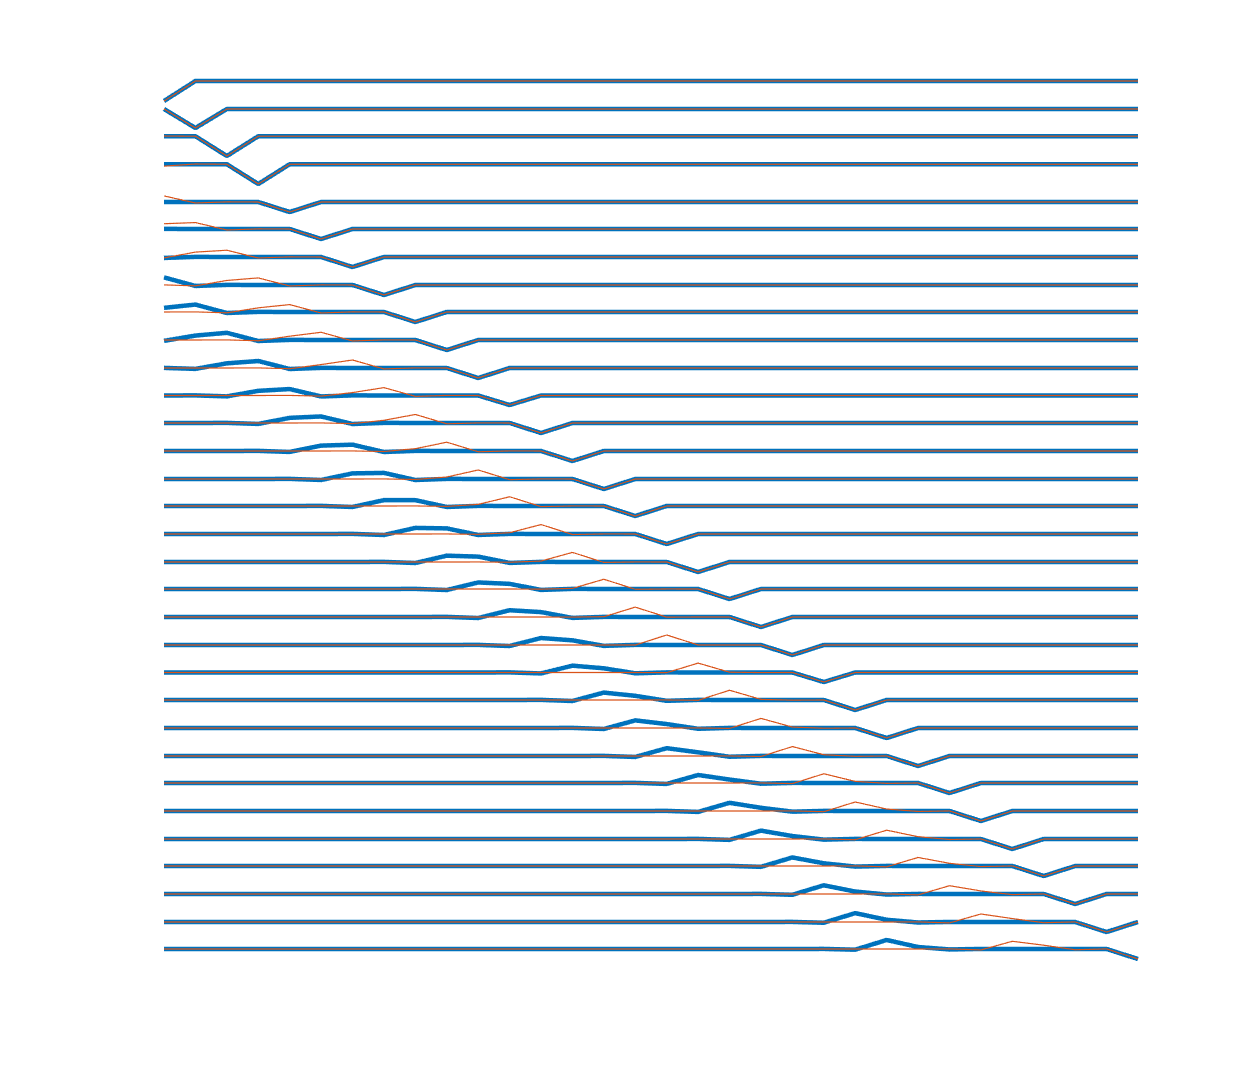

% classic MATLAB script header;
clc;
clear;
close all;
dbstop if error;
format long g;
warning('off');
run("fig2.mlx");

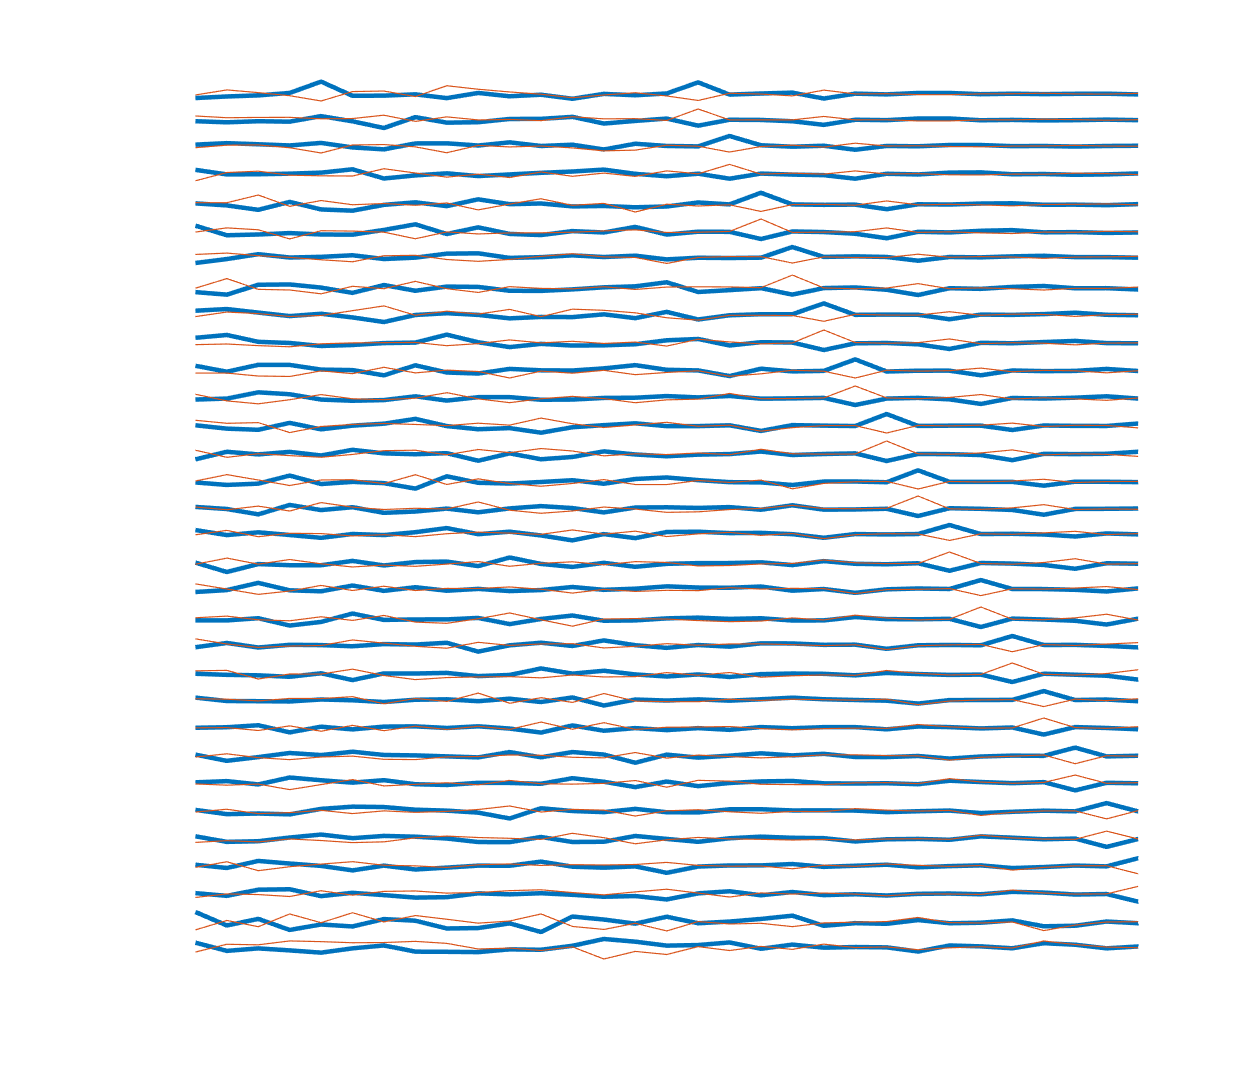

% fig-3
% subplot 3-1, left panel
% singular value decomposition
[u, s, v] = svd(m);
% null space
null_space_svd = u(:, time_length + 2: end)';
tdi_space_svd_y1 = null_space_svd(:, 1: 2: end);
tdi_space_svd_y2 = null_space_svd(:, 2: 2: end);
% plot null space from svd
figure('DefaultAxesFontSize', 16, 'color', [1 1 1], 'Name', 'Piston Phase Wrapped');
for i = 1: 1: time_length + 1
    % signal 1
    subplot(time_length + 1, 1, i)
    plot(tdi_space_svd_y1(i, :), 'linewidth', 2.7);
    hold on;
    plot(tdi_space_svd_y2(i, :), 'linewidth', 0.7);
    % grid on;
    box off;
    set(gca, 'Visible', 'off')
    set(gcf, 'Units', 'centimeters', 'Position', [10 10 70 60]);
    set(gca, 'YTickLabel', [], 'XTickLabel', []); % remove xytick
    xlim([0, time_length]);
    % xlabel('Time [s]', 'fontsize', 20); 
    % ylabel('Amplitude', 'fontsize', 20); 
    % set(gca, 'FontSize', 20, 'linewidth', 1.1);
end

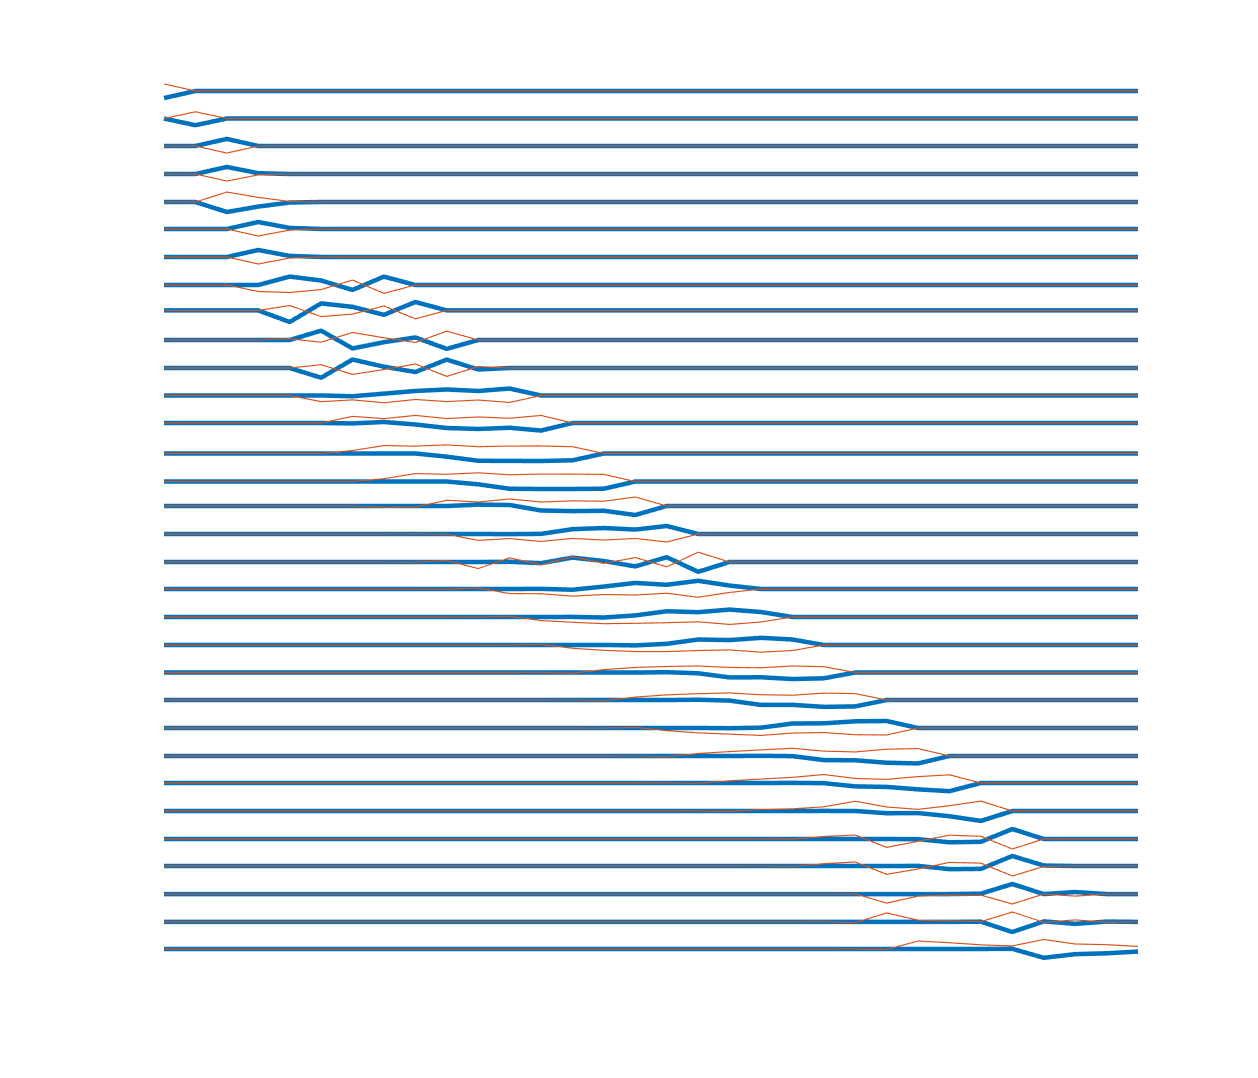

% subplot 3-2, central panel
% turnback method to obtain a null space for the design matrix preserving
% its nonzero pattern
% step 1: 
k = 0;
f_up = [];
f_low = [];
mt = m';
ck = [];
for i = 1: 1: size(mt, 2)
    f_up = [f_up, mt(:, i)];
    if (k < 1)
        if (dependence(f_up) == 0)
            k = k + 1;
            if (k > 0)
                f_low = [f_low, mt(:, i)];
                ck = [ck, i];
            end
        end
    else
        if (dependence(f_up(:, setdiff(1: i, ck))) == 0)
            k = k + 1;
            f_low = [f_low, mt(:, i)];
            ck = [ck, i];
        end
    end
end

% step 2: turn back step
k = 1;
tau = [];
y = zeros(size(mt, 2), size(mt, 2) - size(mt, 1));
for i = 1: 1: length(ck)
    for ii = 1: 1: ck(i)
        iii = ck(i) - ii + 1;
        if (dependence(mt(:, setdiff(iii: ck(i), tau))) == 0)
            tk = iii;
            bk = null(mt(:, setdiff(iii: ck(i), tau)), rank(mt(:, setdiff(iii: ck(i), tau))));
            y(setdiff(iii: ck(i), tau), k) = bk;
            tau = [tau, tk];
        end
    end
    k = k + 1;
end

% plot matrix
figure('DefaultAxesFontSize', 16, 'color', [1 1 1], 'Name', 'Piston Phase Wrapped');
for i = 1: 1: time_length + 1
    % signal 1
    subplot(time_length + 1, 1, i)
    plot(t, y(1: 2: end, i), 'linewidth', 2.7);
    hold on;
    plot(t, y(2: 2: end, i), 'linewidth', 0.7);
    % grid on;
    box off;
    set(gca, 'Visible', 'off')
    set(gcf, 'Units', 'centimeters', 'Position', [10 10 70 60]);
    set(gca, 'YTickLabel', [], 'XTickLabel', []); % remove xytick
    xlim([0, time_length]);
    % xlabel('Time [s]', 'fontsize', 20); 
    % ylabel('Amplitude', 'fontsize', 20); 
    % set(gca, 'FontSize', 20, 'linewidth', 1.1);
end

% subplot 3-3, right panel
